Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84604  table              
  dataMissing       -              84604  table              
  dataWeights       -              94432  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84604  table              
  dataMissing       -              84604  table              
  dataWeights       -              94432  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

Set the response variable to the status column

responseVar = "ResponseVar";

Remove the ID variable from the list of predictors

idVar = "IDVar";

Create a separate bin for missing data values

binMissingData = true;

Use observation weights if they are present

weightsVar = "WeightsVar";
if ~ismember( weightsVar, dataMissing.Properties.VariableNames )
    weightsVar = '';
end

Create the credit scorecard object

sc = creditscorecard(dataMissing,...
    'IDVar',idVar,...
    'ResponseVar',responseVar,...
    'BinMissingData',binMissingData,...
    'WeightsVar',weightsVar);
disp(sc)

  creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'ResponseVar'
               WeightsVar: ''
                 VarNames: {1×11 cell}
        NumericPredictors: {1×6 cell}
    CategoricalPredictors: {'ResStatus'  'EmpStatus'  'OtherCC'}
           BinMissingData: 1
                    IDVar: 'IDVar'
            PredictorVars: {1×9 cell}
                     Data: [1200×11 table]



## Feature Engineering

Automatically bin the scorecard data

sc_binned = autobinning( sc );

## Model Fitting

Fit a logistic regression model to the WOE data. `fitmodel` internally bins the training data, transforms it into WOE values, maps the response variable so that `'Good'` is `1`, and fits a linear logistic regression model. By default, `fitmodel` uses a stepwise procedure to determine which predictors should be in the model.

[sc_binned,mdl] = fitmodel(sc_binned);

1. Adding CustIncome, Deviance = 1490.8527, Chi2Stat = 32.588614, PValue = 1.1387992e-08
2. Adding TmWBank, Deviance = 1467.1415, Chi2Stat = 23.711203, PValue = 1.1192909e-06
3. Adding AMBalance, Deviance = 1455.5715, Chi2Stat = 11.569967, PValue = 0.00067025601
4. Adding EmpStatus, Deviance = 1447.3451, Chi2Stat = 8.2264038, PValue = 0.0041285257
5. Adding CustAge, Deviance = 1442.8477, Chi2Stat = 4.4974731, PValue = 0.033944979
6. Adding ResStatus, Deviance = 1438.9783, Chi2Stat = 3.86941, PValue = 0.049173805
7. Adding OtherCC, Deviance = 1434.9751, Chi2Stat = 4.0031966, PValue = 0.045414057

Generalized linear regression model:
    ResponseVar ~ [Linear formula with 8 terms in 7 predictors]
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    

scores = probdefault(sc_binned,sc_binned.Data);

## **Assessment of Predictive Ability of Credit Rating Models**

Credit scoring is one of the most widely used credit risk analysis tools to rank borrowers by their credit worthiness. Credit scoring is performed using a credit scorecard. Credit scorecards model different characteristics of a customer (age, residential status, etc.), translate them into points and sum the points to compute the credit score. The credit score summarizes the credit worthiness of customers. High credit scores correspond to low-risk customers, and conversely. 

In order to assess the predictive ability of a credit scorecard there exists several statistical methodologies, which require the following:

- scores associated to each name or observation in the credit scorecard ($scores$)

- probability of default corresponding to each score ($defaultProbs$)

- indicator variable to signal if an observation is a defaulter or otherwise ($defaultIndicators$)

In order to better evaluate the capability of model to classify we split the dataset into training and test datasets.

cv = cvpartition(sc_binned.Data.(sc_binned.ResponseVar), 'HoldOut') ;
trainingIdx = training(cv) ;
testIdx = test(cv) ;

Setting up training data

scores.training = score(sc_binned, sc_binned.Data(trainingIdx,:));
defaultProbs.training = probdefault(sc_binned, sc_binned.Data(trainingIdx,:));
defaultIndicators.training = sc_binned.Data.(sc_binned.ResponseVar)(trainingIdx) ~= sc_binned.GoodLabel;

Setting up test data

scores.test = score(sc_binned, sc_binned.Data(testIdx,:));
defaultProbs.test = probdefault(sc_binned, sc_binned.Data(testIdx,:));
defaultIndicators.test = sc_binned.Data.(sc_binned.ResponseVar)(testIdx) ~= sc_binned.GoodLabel;

The subsequent sections each calculate one model validation metric in a self-contained manner. The results are stored in a collection object:

MH = mrm.data.validation.MetricsHandler;

and summarised at the end of the script.

### **Cumulative Accuracy Profile (CAP)**

CAP of a model represents the cumulative number of defaulters along the y-axis versus the corresponding cumulative number of all borrowers along the x-axis. 

The scores of given observations are sorted (in ascending order) from riskiest to safest. For a given fraction `M` of the total borrowers, the height of the CAP curve is the fraction of defaulters whose scores are less than or equal to the maximum score of the fraction `M`.

A perfect rating model will assign the lowest scores to the defaulters. On the other hand, a random model without any discriminative power would assign scores randomly and therefore fraction *x* of all debtors with lowest rating scores will contain *x* percent of all defaulters. CAP curve of rating systems calibrated to work with real data would lie somewhere in between. The quality of a rating system is measured by the Accuracy Ratio (AR). It is defined as:


$$\textrm{Accuracy}\;\textrm{Ratio}\;\left(\textrm{AR}\right)=\frac{\textrm{Area}\;\textrm{between}\;\textrm{CAP}\;\textrm{curve}\;\textrm{of}\;\textrm{rating}\;\textrm{model}\;\textrm{being}\;\textrm{validated}\;\&\;\textrm{CAP}\;\textrm{curve}\;\textrm{of}\;\textrm{the}\;\textrm{random}\;\textrm{model}}{\textrm{Area}\;\textrm{between}\;\textrm{CAP}\;\textrm{curve}\;\textrm{of}\;\textrm{perfect}\;\textrm{rating}\;\textrm{model}\;\&\;\textrm{CAP}\;\textrm{curve}\;\textrm{of}\;\textrm{the}\;\textrm{random}\;\textrm{model}}$$


The closer to unity $\textrm{AR}$ is, the better the scoring model.

Training data

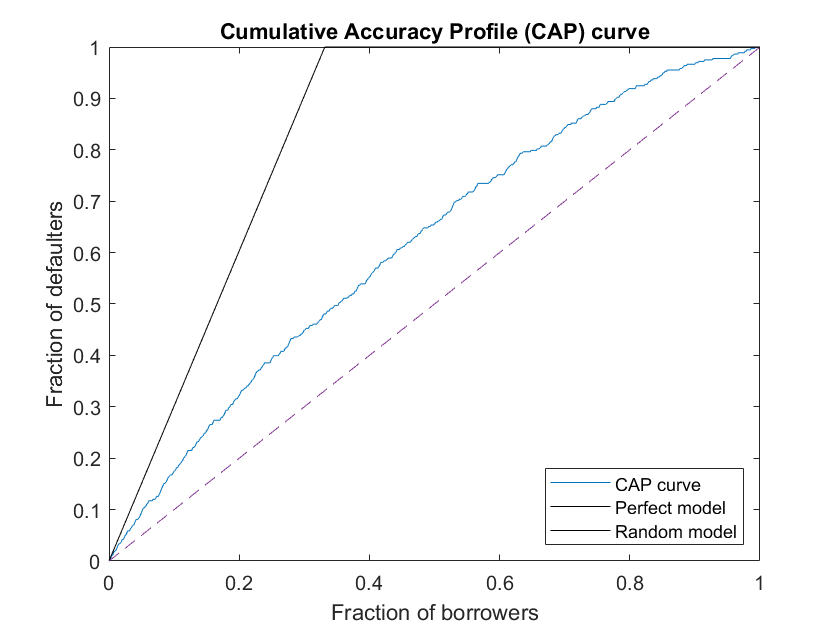

CAPMetric.training = mrm.data.validation.pd.CAPAccuracyRatio(defaultIndicators.training, scores.training);
CAPMetric.training.visualize;

CAPMetric.training.displayResult;

Accuracy ratio is 0.345


Test data

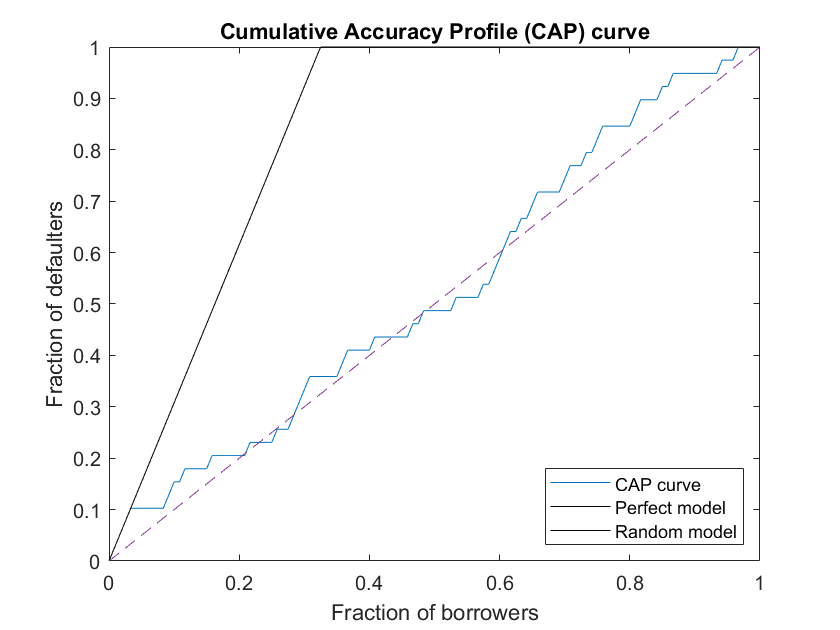

CAPMetric.test = mrm.data.validation.pd.CAPAccuracyRatio(defaultIndicators.test, scores.test);
CAPMetric.test.visualize;

CAPMetric.test.displayResult;

Accuracy ratio is 0.07629


MH.append(CAPMetric.test);

### **Binomial Test **

Binomial Test is a test of quality of estimates of probability of default. The idea is to understand if the deviations of estimates of probability of default are purely random or whether they occur systematically. A systematic underestimation of probability of default needs to critically assessed by validators. The binomial test works as follows:

      null hypothesis, H0:              the PD of a rating category is correct

      alternative hypothesis, H1:   the PD of a rating category is underestimated

For any given rating, there's a well-defined default probability $p$. Supposing there are $n$ names with this given rating, define 

    
$$P_k = \sum_{i = k}^n  {n \choose i} p^i (1-p)^{n-i}.$$


We then have $1 = P_0 > P_1 > .... > P_n = p^n$, so that (at least if $p < 1$ and $n$ is large), we have a well defined critical value associated to the confidence level, $q$, defined as

    
$$k(q) = \min \{ k \,| \, P_k \leq 1-q \}.$$


In other words, $k(q)$ is the smallest number such that there occuring more than $k(q)$ defaults in the rating set is less than $1-q$. For example, if $q = 0.95$, then the rating set should have more than $k(q)$ defaults with probability less than $5\%$.

Note that if $n$ is small, the minimal $P_k$ , i.e. $p^n$, need not be very small, so there may not be enough data to have a meaningful test for this rating class. The closer the binomial test failure rate is to zero, the better the quality of the estimate.

q = 0.95;

Training Data

BinMetric.training = mrm.data.validation.pd.BinomialTest(defaultIndicators.training, defaultProbs.training, scores.training, q);
BinMetric.training.displayResult;

Binomial test failure rate is 0.017.
Exceedances occur at the following scores:
-0.62536 -0.38409 -0.31874 -0.12852 0.114 0.26306 0.2884 0.50396 0.6317 0.69167 0.81391 0.84196 0.87014 0.92332 1.0727 1.2175


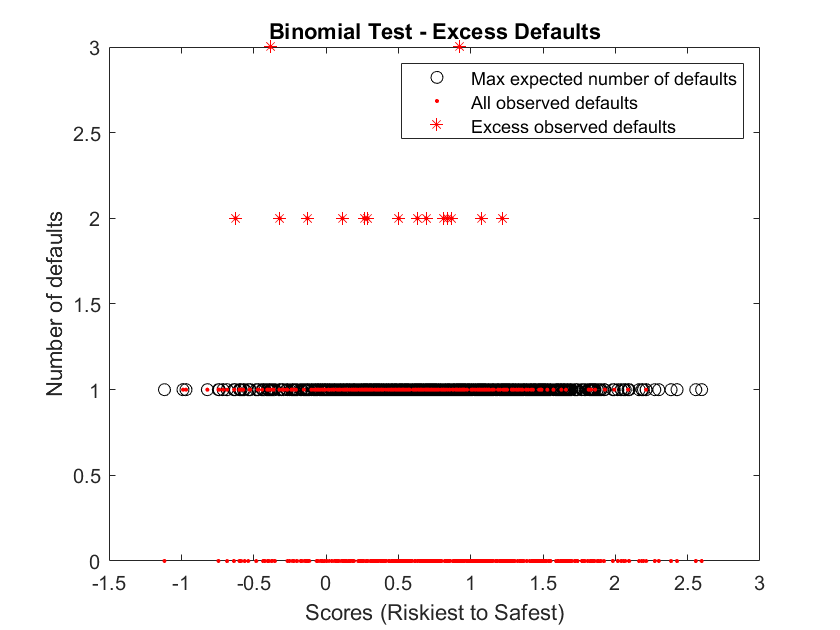

BinMetric.training.visualize;

Test Data

BinMetric.test = mrm.data.validation.pd.BinomialTest(defaultIndicators.test, defaultProbs.test, scores.test, q);
BinMetric.test.displayResult;

Binomial test failure rate is 0.0086.
Exceedances occur at the following scores:
-0.4516


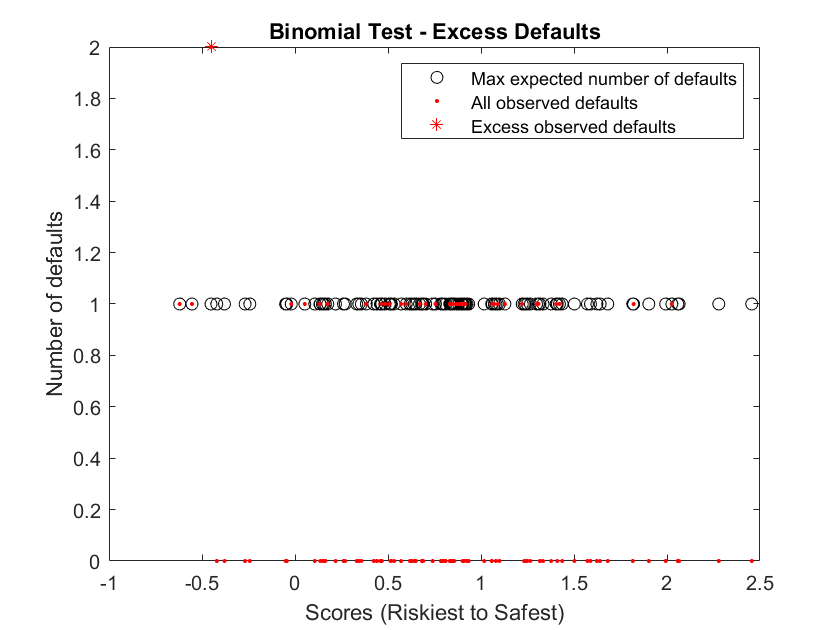

BinMetric.test.visualize;

MH.append(BinMetric.test);

### **Summary **

In the above sections, several assessment metrics/tests were calculated to assess the predictive ability of the credit rating model associated with a credit score card. Here is the summary of the metrics/tests calculated:

Test Data

MH.displaySummary ;

               Metric                 Value  
    ____________________________    _________

    "Accuracy ratio"                  0.07629
    "Binomial test failure rate"    0.0086207

